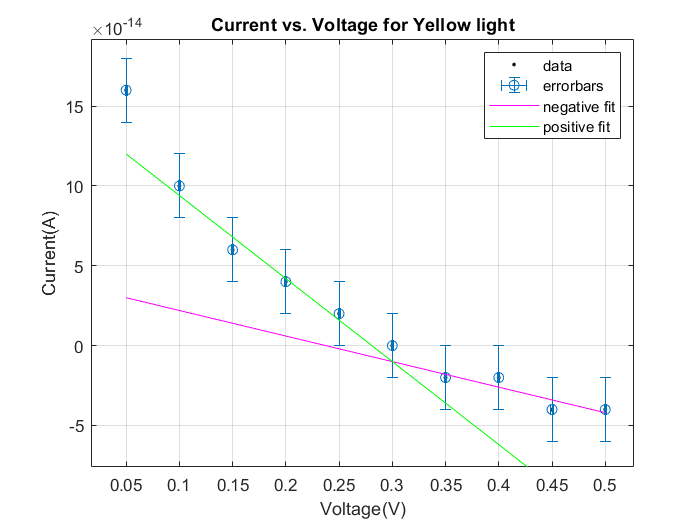

plot(YELLOWvoltage,YELLOWcurrent,'.k')
hold on
%%CREATING ERRORBARS
xneg=0.001.*[1 1 1 1 1 1 1 1 1 1];
xpos=xneg;
yneg=(0.2e-13).*[1 1 1 1 1 1 1 1 1 1];
ypos=yneg;
errorbar(YELLOWvoltage,YELLOWcurrent,yneg,ypos,xneg,xpos,'o');

%%NEGATIVE SIDE FIT

%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =    -1.600e-13 \mp 1.217e-13 
  %     p2 =     3.800e-14 \mp1.417e-14

%Goodness of fit:
 % SSE: 8e-29
 % R-square: 0.8
 % Adjusted R-square: 0.7
 % RMSE: 6.325e-15
  p1 =    -1.6e-13 ;
   p2 =     3.8e-14;
   f=p1.*YELLOWvoltage+p2;
plot(YELLOWvoltage,f,'m');


%%POSITIVE SIDE FIT

%Linear model Poly1:
 %    g = p3*x + p4
%Coefficients (with 95% confidence bounds):
 %      p3 =    -5.200e-13  \mp 1.490e-13
 %      p4 =    1.460e-13  \mp 0.274e-13

%Goodness of fit:
 % SSE: 1.2e-28
 % R-square: 0.9657
 % Adjusted R-square: 0.9486
% RMSE: 7.746e-15
p3 =    -5.2e-13;
p4 =    1.46e-13 ;
g = p3*YELLOWvoltage + p4;

plot(YELLOWvoltage,g,'g');


%%LABELING
grid on

xlim([0.017 0.527])
ylim([-0.000000000000076 0.000000000000192])
legend({'data','errorbars','negative fit','positive fit'})
title('Current vs. Voltage for Yellow light')
xlabel('Voltage(V)')
ylabel('Current(A)')